# Image Processing Classwork 1

## Carter Harris, Mark Belanger, Meagan Lipsman

### 9/6/24

low_res = imread("low res.jpg");
high_res = imread("high res.jpg");
red_img = imread("red one.jpg");
yellow_img = imread("yellow one.jpg");
arciad_img = imread("ARCAid.jpg")

arciad_img = 480×640×3 uint8 array
arciad_img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  

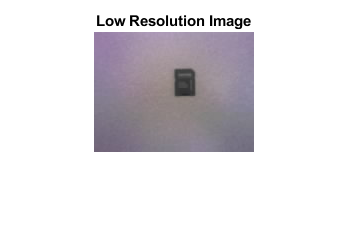

imshow(low_res)
title("Low Resolution Image")

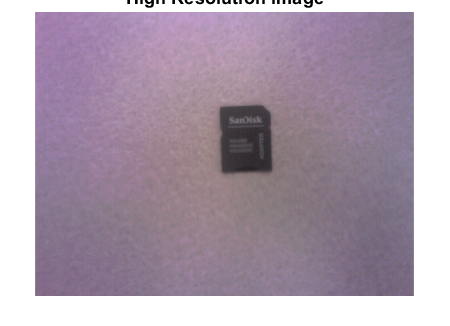

imshow(high_res)
title("High Resolution Image")

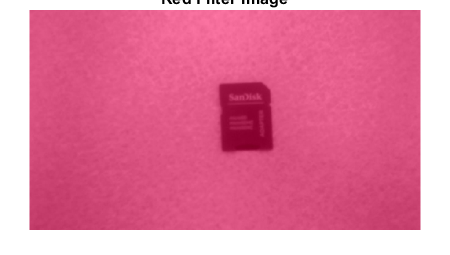

imshow(red_img)
title("Red Filter Image")

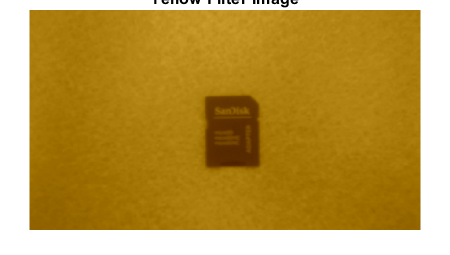

imshow(yellow_img)
title("Yellow Filter Image")

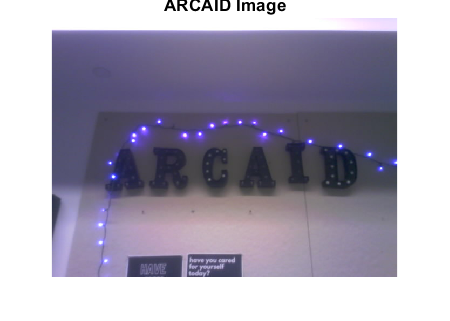

imshow(arciad_img)
title("ARCAID Image")

low_res_grey = rgb2gray(low_res);
high_res_grey = rgb2gray(high_res);
red_img_grey = rgb2gray(red_img);
yellow_img_grey = rgb2gray(yellow_img);
arciad_grey = rgb2gray(arciad_img)

arciad_grey = 480×640 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255  

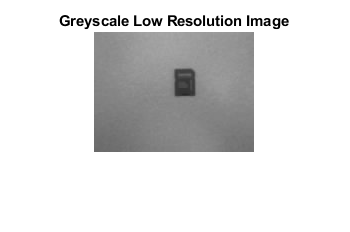

imshow(low_res_grey)
title("Greyscale Low Resolution Image")

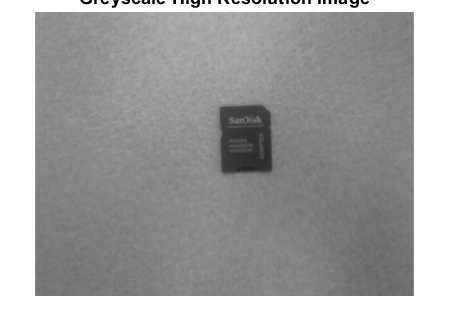


imshow(high_res_grey)
title("Greyscale High Resolution Image")

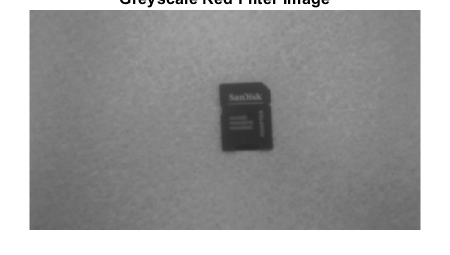


imshow(red_img_grey)
title("Greyscale Red Filter Image")

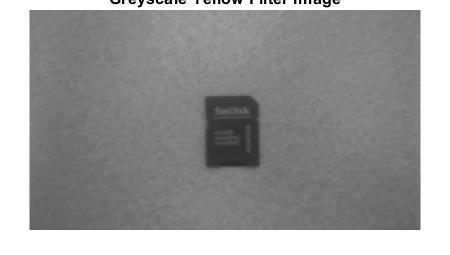


imshow(yellow_img_grey)
title("Greyscale Yellow Filter Image")

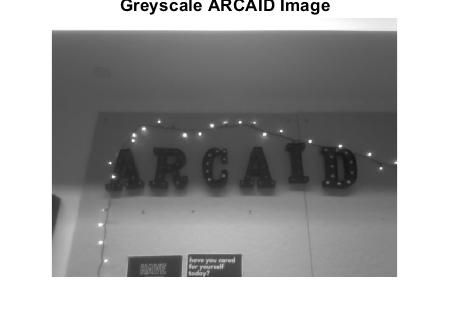


imshow(arciad_grey)
title("Greyscale ARCAID Image")

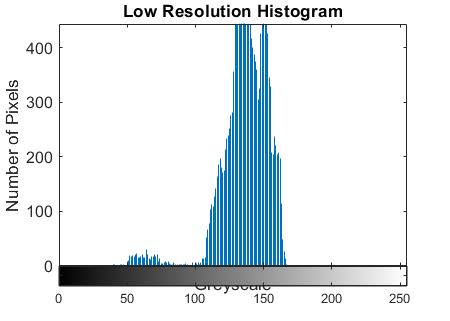

imhist(low_res_grey)
title("Low Resolution Histogram")
xlabel("Greyscale")
ylabel("Number of Pixels")

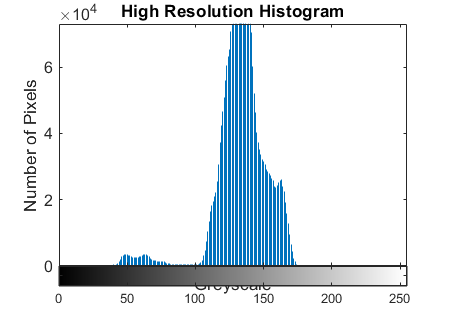


imhist(high_res_grey)
title("High Resolution Histogram")
xlabel("Greyscale")
ylabel("Number of Pixels")

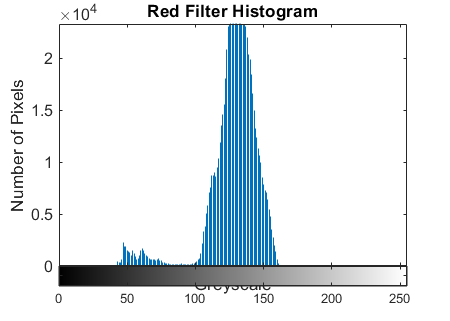


imhist(red_img_grey)
title("Red Filter Histogram")
xlabel("Greyscale")
ylabel("Number of Pixels")

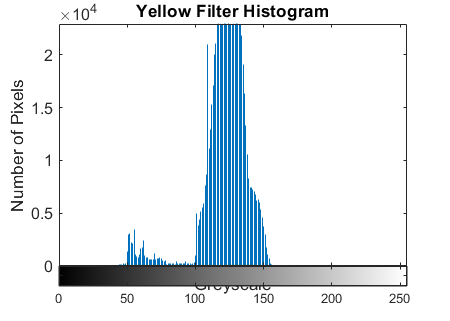


imhist(yellow_img_grey)
title("Yellow Filter Histogram")
xlabel("Greyscale")
ylabel("Number of Pixels")

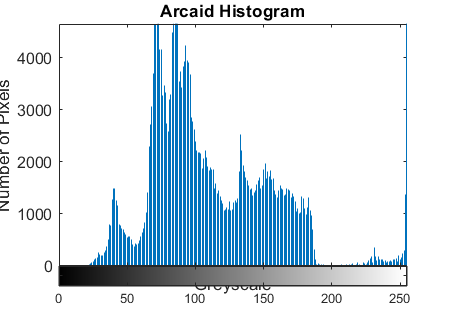


imhist(arciad_grey)
title("Arcaid Histogram")
xlabel("Greyscale")
ylabel("Number of Pixels")

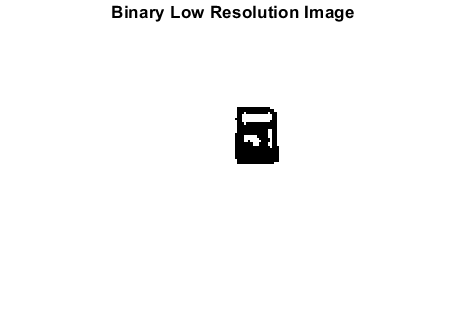

threshold_value = 70;
arcaid_threshold = 57;

low_res_binary = low_res_grey > threshold_value;
imshow(low_res_binary)
title("Binary Low Resolution Image")

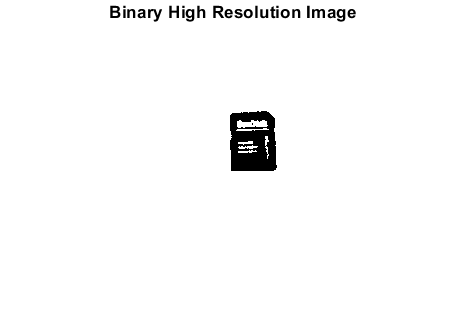


high_res_binary = high_res_grey > threshold_value;
imshow(high_res_binary)
title("Binary High Resolution Image")

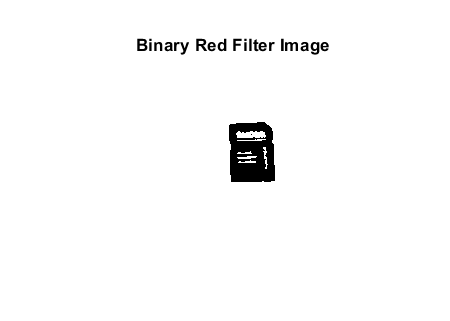


red_img_binary = red_img_grey > threshold_value;
imshow(red_img_binary)
title("Binary Red Filter Image")

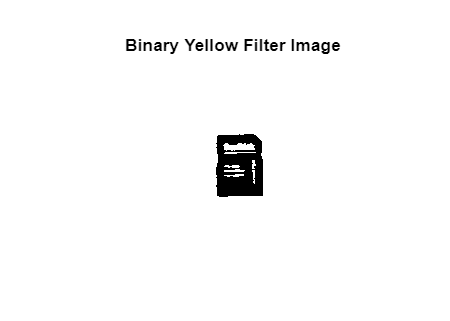


yellow_img_binary = yellow_img_grey > threshold_value;
imshow(yellow_img_binary)
title("Binary Yellow Filter Image")

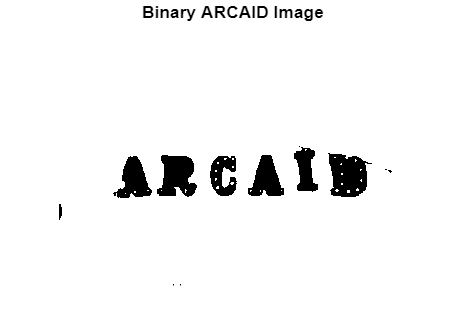


arciad_binary = arciad_grey > arcaid_threshold;
imshow(arciad_binary)
title("Binary ARCAID Image")

## Reflection Questions

**6a.** We chose both threshold values based on the histogram and used trial and error to fine tune the value. For both the SD card images and the ARCAID image we had dark objects against a light background that we were trying to identify. Because of that, there were pretty clear spikes on the extremes of the greyscale. We picked threshold values that were in the valley of those spikes.

**6b. **For our images, this processing worked very well to identify the objects in the image. This was due to the fact that our images were already almost in grayscale and had very distinct dark objects on light backgrounds. We see how there could be issues with this method if the images were more complex as it would be harder to make those clear distinctions.